%EE 354
%Lisa Jacklin
%10/8/2022
%Computer Exercises HW 6
%note that 3A is all explaination of what will be happening in 3B1 and 3B2

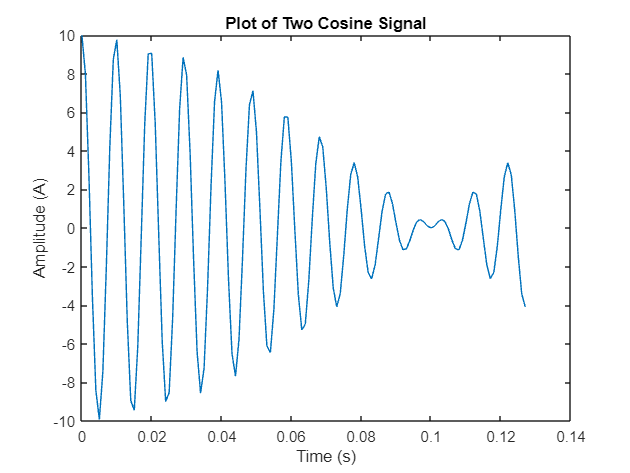


%Computer Exercise 3B.1
% 3B.1.b

% %assumptions given in
%these values should be taken into to the function created...
A1 = 5; %amplitudes
A2 = 5;
f1 = 100;%frequencies in Hz
f2 = 105;
phase1 = 0;
phase2 = 0;
fs = 1000; %sampling frequency choosen and ts from fs...
ts = 1/fs;
T = 127e-3; %in milliseconds which is shown with e-3

%this with the given assumptions is what will be graphed...
[signal, time] = twoCosine(A1, f1, phase1, A2, f2, phase2, T, fs);

plot (time, signal);
title ("Plot of Two Cosine Signal")
    xlabel('Time (s)')
    ylabel("Amplitude (A)")

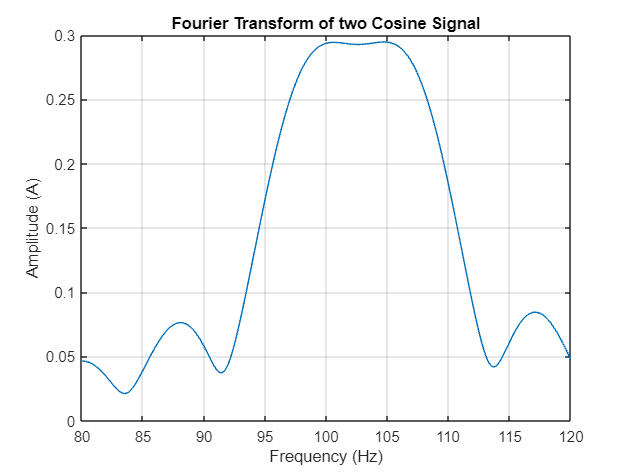



% Now, to generate frequency axis for the fourier transform of the sample
N = 2^15; %Noting that the processor works best with root 2
df = fs/N;
f = -(fs/2 - df) : df : fs/2;

% Plot Fourier transform of sampled signal
S = ts*fftshift(fft(signal, N)); %the signal is the same of the one defined above...
plot(f, abs(S));
grid on;
xlim([80, 120]); % ylim([]);
    title("Fourier Transform of two Cosine Signal")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude (A)")

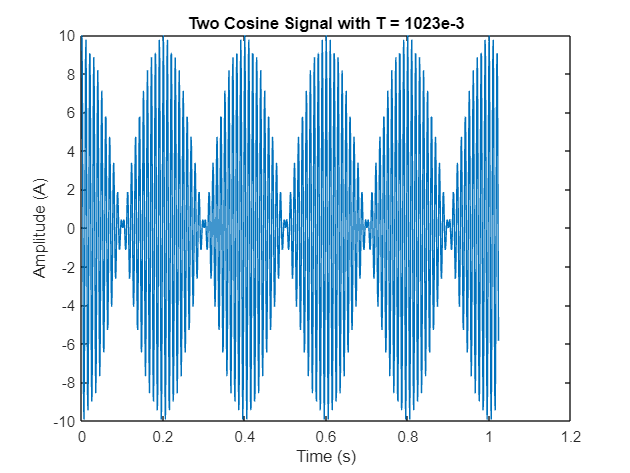

%3b.1.c
%now, a different T value is determined, and must be plotted, as well as
%transformed just like  it was shown above.
T = 1023e-3;
%now using the function again to define 
[signal, time] = twoCosine(A1, f1, phase1, A2, f2, phase2, T, fs);

plot (time, signal);
    title ("Two Cosine Signal with T = 1023e-3")
    xlabel("Time (s)")
    ylabel("Amplitude (A)")

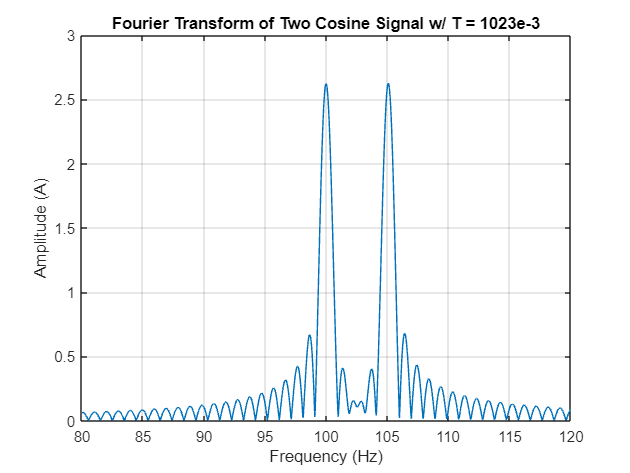


%now for the fourier transform of the new sample signal...
S = ts*fftshift(fft(signal, N));
plot (f, abs(S));
grid on;
xlim([80, 120]); % this should limit the frequency between the 80 to 120 specified
    title ("Fourier Transform of Two Cosine Signal w/ T = 1023e-3")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude (A)")

%As can be seen between the differences of these two functions, in the time
%domain, it can be seen that T of course being the period of the function,
%changes the amount of times that a signal can cycle through during a
%specified time range. 

%Considering the frequency domain, it can be seen that between 100-105Hz,
%the slight dip that can be seen in the first signal fourier transform is
%far less condensed in comparison to the second fourier transform signal
%which has a dip between the two amplitude spikes.

%3B.2.a
%for this secion, we are different set of variables, but will continue to
%use the function created cause it works!

A1 = 5;
A2 = 0;
f1 = 150;
phase = 0;
T = 1022e-3;
fs = 500;
ts = 1/fs;

%this sould be the updated function for this problem!
[signal, time] = twoCosine(A1, f1, phase1, A2, f2, phase2, T, fs)

signal =     5.0000   -1.5451   -4.0451    4.0451    1.5451   -5.0000    1.5451    4.0451   -4.0451   -1.5451    5.0000   -1.5451   -4.0451    4.0451    1.5451   -5.0000    1.5451    4.0451   -4.0451   -1.5451    5.0000   -1.5451   -4.0451    4.0451    1.5451   -5.0000    1.5451    4.0451   -4.0451   -1.5451    5.0000   -1.5451   -4.0451    4.0451    1.5451   -5.0000    1.5451    4.0451   -4.0451   -1.5451    5.0000   -1.5451   -4.0451    4.0451    1.5451   -5.0000    1.5451    4.0451   -4.0451   -1.5451


time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


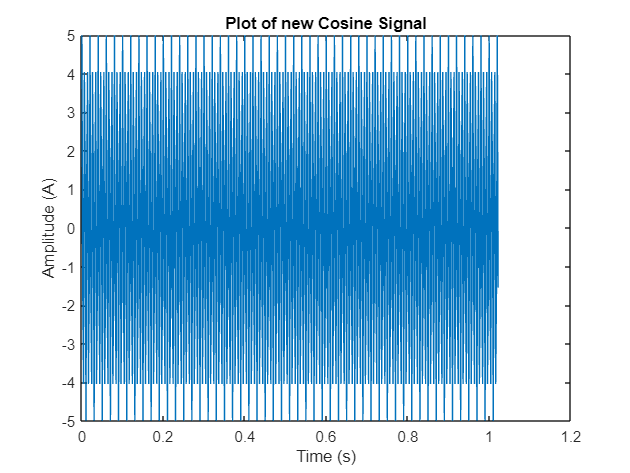


%now normal plot of the new signal
plot (time, signal);
    title ("Plot of new Cosine Signal")
    xlabel("Time (s)")
    ylabel("Amplitude (A)")

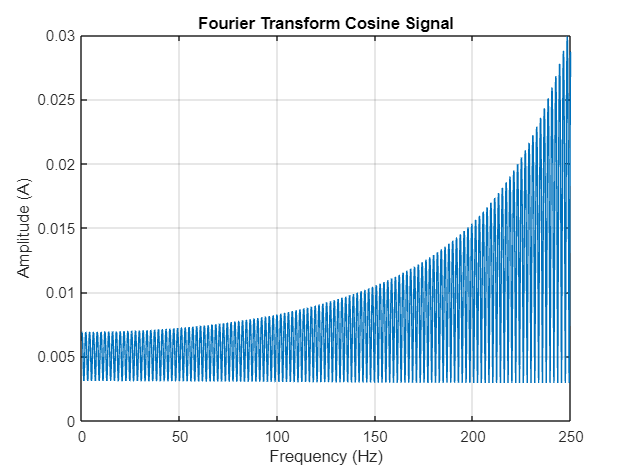


%now, for the fourier transofmr
S = ts*fftshift(fft(signal, N));

plot(f, abs(S));
grid on;
xlim ([0,250]) %specifed frequency range...
    title("Fourier Transform Cosine Signal")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude (A)")

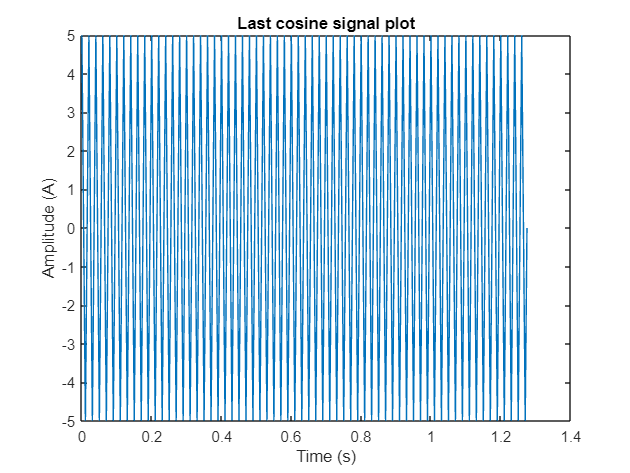

%3B.2.b
%one last set of values given that will be measured between 0 and 100 Hz in
%the frequency domain.

A1 = 5;
A2 = 0;
f1 = 150;
phase1 = 0;
T = 1275e-3; %this is a changed value
fs = 200; %another change
tw = 1/fs;
%resulting equation:
[signal, time] = twoCosine (A1, f1, phase1, A2, f2, phase2, T, fs);

%time domain
plot (time, signal);
    title ("Last cosine signal plot")
    xlabel("Time (s)")
    ylabel("Amplitude (A)")

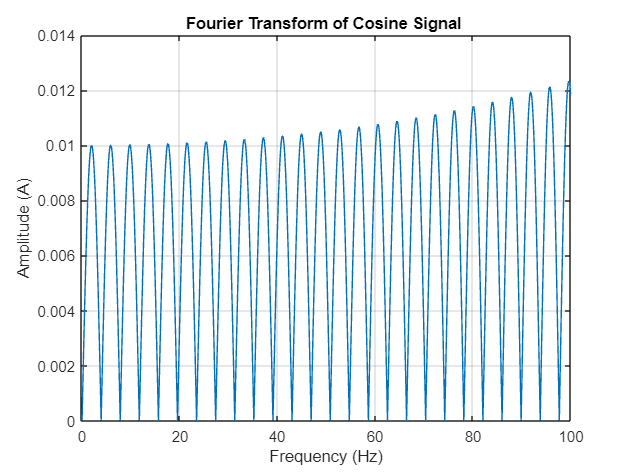


%Lastly, fourier transform of this last signal
S = ts*fftshift (fft(signal, N));
plot (f, abs(S));
grid on;
xlim([0,100]);
    title ("Fourier Transform of Cosine Signal ")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude (A)")

%These two functions in the frequency domain show the most difference
%between the two. Most moticeable is the curve to higher amplitudes in the
%first cosine signal shown in 3B.2.b, but as can be seen by the second
%signal in the plot above, there is a slight change in amplitude as the
%frequency gets larger.


